%% step1_gen_data.m
clc; clear; close all;

% 1. 读取输入图像（建议先缩放到较小分辨率，如 64x64 或 128x128，加快仿真速度）
img_raw = imread('C:\Users\jingzifu\Desktop\OIP.jpg'); % 替换为你自己的图片路径
if size(img_raw, 3) == 1
    img_rgb = cat(3, img_raw, img_raw, img_raw);
else
    img_rgb = img_raw;
end

WIDTH  = 64;   % 图像宽度
HEIGHT = 64;   % 图像高度
img_rgb = imresize(img_rgb, [HEIGHT, WIDTH]);

% 2. 导出为 Verilog 可读的 24-bit RGB 文本 (R[23:16], G[15:8], B[7:0])
fid = fopen('src_img.txt', 'w');
for r = 1:HEIGHT
    for c = 1:WIDTH
        R = img_rgb(r, c, 1);
        G = img_rgb(r, c, 2);
        B = img_rgb(r, c, 3);
        fprintf(fid, '%02X%02X%02X\n', R, G, B);
    end
end
fclose(fid);
fprintf('成功生成 src_img.txt (分辨率: %dx%d)\n', WIDTH, HEIGHT);

成功生成 src_img.txt (分辨率: 64x64)


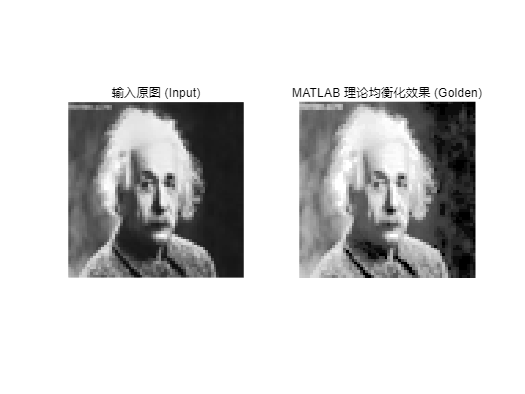


% 3. 生成 MATLAB 黄金参考图 (Golden Model)
% 对应你的 Verilog：RGB -> YCbCr -> 提取 Y -> 直方图均衡化 -> 复制为 RGB
img_ycbcr = rgb2ycbcr(img_rgb);
Y = img_ycbcr(:,:,1);
Y_equ = histeq(Y); % MATLAB 的直方图均衡化
img_golden = cat(3, Y_equ, Y_equ, Y_equ);

% 保存并显示黄金参考图
imwrite(img_golden, 'matlab_golden.png');
figure('Name', '输入原图 vs MATLAB理论效果');
subplot(1,2,1); imshow(img_rgb); title('输入原图 (Input)');
subplot(1,2,2); imshow(img_golden); title('MATLAB 理论均衡化效果 (Golden)');